## 1. Read the csv file, load data, process dates, select features(predictors) 

clear; clc;

%% 1) Load data (preserve original column names)
data = readtable('data/WeldResultTable_20211124_162110.csv', ...
    'VariableNamingRule', 'preserve');

%% Try to convert DateTime co\lumn, or fall back to row index if all else fails

data.DateTime = datetime(data.DateTime, ...
    'InputFormat', 'yyyy/MM/dd HH:mm:ss', ...
    'Locale', 'en_US'); 
rawTime = data.DateTime
try
    % Try parsing as datetime
    dt = datetime(rawTime);
    timeSeconds = seconds(dt - dt(1));  % time since first
    
catch ME1
    fprintf('First datetime() parsing failed: %s\n', ME1.message);
    try
        % Try as numeric (e.g., Excel serial date)
        timeSeconds = rawTime - rawTime(1);
        if ~isnumeric(timeSeconds)
            error('Converted time is not numeric.');
        end
    catch ME2
        fprintf('Second numeric conversion failed: %s\n', ME2.message);
        warning('Falling back to row index as time axis.\n');
        timeSeconds = (1:height(data))';  % fallback
    end
end

%% 2) Select relevant features (as requested)
selectedFeatures = data(:, {
    'DateTime','CycleCounter','MaxWeldForce','WeldAbsolute', ...
    'TriggerDistance','WeldTime', ...
    'WeldPeakPower',...
    'CycleTime', 
});

% Drop rows with any missing values in these columns
validIdx = ~any(ismissing(selectedFeatures), 2);
selectedFeatures = selectedFeatures(validIdx, :);

% Guard: need DateTime present & valid
if ~ismember('DateTime', selectedFeatures.Properties.VariableNames)
    error('DateTime column missing after selection.');
end
if ~isdatetime(selectedFeatures.DateTime)
    error('DateTime must be datetime after parsing.');
end

## 2. Set a threshold for zscore and plot anomalies each parameter


zscore_threshold = 4;
%% 3) Identify numeric parameter columns (exclude DateTime & non-numeric like WeldMode if not numeric)
isNum = varfun(@isnumeric, selectedFeatures, 'OutputFormat', 'uniform');
numVarNames = selectedFeatures.Properties.VariableNames(isNum);

% Ensure DateTime not included (it isn't numeric, but just in case)
numVarNames = setdiff(numVarNames, {'DateTime','CycleCounter'});
numVarNames = {
    'MaxWeldForce'
    'WeldTime',
    'WeldPeakPower', 
    'WeldAbsolute', ;
    'TriggerDistance',
    'CycleTime',
};
%% 4) Normalize numeric data (z-score per column)
normTable = table(selectedFeatures.DateTime, 'VariableNames', {'DateTime'});
for i = 1:numel(numVarNames)
    v = numVarNames{i};
    x = selectedFeatures.(v);
    mu = mean(x, 'omitnan');
    sd = std(x, 'omitnan');
    if sd == 0 || isnan(sd)
        z = zeros(size(x)); % constant series -> all zeros
    else
        z = (x - mu) ./ sd;
    end
    normTable.(v) = z;
end

%% 5) Plot ORIGINAL values vs DateTime with anomalies in red
n = numel(numVarNames);
if n == 0
    warning('No numeric variables found to plot.');
else
    figTitle = "Anomalies > " + zscore_threshold;
    figure('Name', figTitle, 'Color', 'w');
    % pick a tidy grid
    ncols = 1;  % or adjust as needed
    nrows = ceil(n / ncols);
    tiledlayout(nrows, ncols, 'TileSpacing','compact','Padding','compact');

    for i = 1:n
        v = numVarNames{i};
        x = selectedFeatures.(v);
        z = normTable.(v);
        time = selectedFeatures.DateTime;

        % Find anomalies (z-score > 3 or < -3)

        anomalyIdx = abs(z) > zscore_threshold;

        nexttile;
        plot(time, x, 'b-','LineWidth',1); hold on;
        plot(time(anomalyIdx), x(anomalyIdx), 'ro','MarkerSize',4,'MarkerFaceColor','r');
        
        title(v, 'Interpreter','none');
        xlabel('DateTime'); ylabel(v);
        grid on;
    end
end

%% 6) Anomaly Detection using Z-score
threshold = 2; % Define the Z-score threshold for anomaly detection
anomalies = table(selectedFeatures.DateTime, 'VariableNames', {'DateTime'});

for i = 1:numel(numVarNames)
    v = numVarNames{i};
    zScores = (selectedFeatures.(v) - mean(selectedFeatures.(v), 'omitnan')) ./ std(selectedFeatures.(v), 'omitnan');
    anomalyIdx = abs(zScores) > threshold; % Identify anomalies
    anomalies.(v) = anomalyIdx; % Store anomaly indicators
end

% Display anomalies
if any(any(anomalies{:, 2:end}))
    fprintf('Anomalies detected (z-score > %.1f) in the following variables:\n', threshold);
    for i = 1:numel(numVarNames)
        v = numVarNames{i};
        if any(anomalies.(v))
            fprintf('%s: %d anomalies detected\n', v, sum(anomalies.(v)));
        end
    end
else
    fprintf('No anomalies detected in the selected variables.\n');
end

% Assuming your datetime is parsed correctly
t = selectedFeatures.DateTime;

% Use the same z-scores
anomalies = abs(zscore(selectedFeatures.CycleTime)) > threshold;
times = t(anomalies);

% Group anomalies by date
dates = dateshift(times, 'start', 'day');
T = table(dates);
summary = groupsummary(T, 'dates');

figure;
bar(summary.dates, summary.GroupCount);
xlabel('Date'); ylabel('CycleTime anomalies');
title('CycleTime Anomalies per Day');
Z = zscore(table2array(selectedFeatures(:, {'CycleTime','MaxWeldForce','WeldTime','WeldPeakPower','WeldAbsolute','TriggerDistance'})));
anomalyFlags = abs(Z) > threshold;
rowsWithMultiple = sum(anomalyFlags, 2) >= 4;
numCriticalAnomalies = sum(rowsWithMultiple);

fprintf('Rows with 2+ anomalies: %d (%.2f%%)\n', numCriticalAnomalies, 100 * numCriticalAnomalies / height(selectedFeatures));
selectedFeatures.AnomalyScore = sum(abs(Z) > 3, 2);
anomalousRows = selectedFeatures(selectedFeatures.AnomalyScore > 0, :);
anomalyfilename = "output/anomalies_detected_threshold_" + threshold + ".csv";
writetable(anomalousRows, anomalyfilename);

## **3. Threshold is based on limits set based on recipes or infer limits dynamically using data, run code under section 4.**

**Note: if your underlying data file changes perform the **

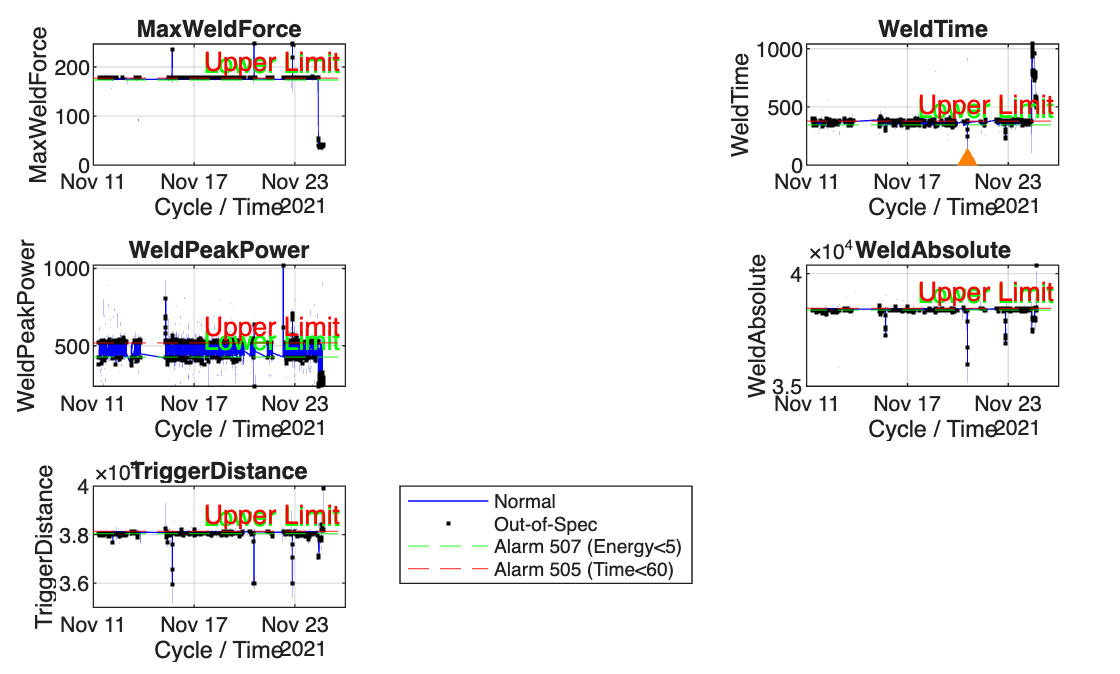

% Choose time axis
if ismember('DateTime', selectedFeatures.Properties.VariableNames) && isdatetime(selectedFeatures.DateTime)
    timeAxis = selectedFeatures.DateTime;
elseif ismember('CycleCounter', selectedFeatures.Properties.VariableNames)
    timeAxis = selectedFeatures.CycleCounter;
else
    timeAxis = (1:height(selectedFeatures))';
end

% Define parameter list and their limits
params = {
    'MaxWeldForce', 173.500, 177.500;
    'WeldTime', 346.000, 378.000;
    'WeldPeakPower', 426.500, 518.500;
    'WeldAbsolute', 38383.500, 38459.500;
    'TriggerDistance', 38041.000, 38137.000;
};

% Prepare alarm flags
alarm507 = false(height(selectedFeatures),1);  % Energy < 5
alarm505 = false(height(selectedFeatures),1);  % Time < 60

if ismember('WeldEnergy', selectedFeatures.Properties.VariableNames)
    alarm507 = selectedFeatures.WeldEnergy < 5;
end
if ismember('WeldTime', selectedFeatures.Properties.VariableNames)
    alarm505 = selectedFeatures.WeldTime < 60;
end

% Plot setup
figure('Name','Welding Analysis with Alarm Types','Color','w');
tiledlayout(3,2,'TileSpacing','compact','Padding','compact');

for i = 1:size(params,1)
    paramName = params{i,1};
    lower = params{i,2};
    upper = params{i,3};

    if ~ismember(paramName, selectedFeatures.Properties.VariableNames)
        warning('Missing variable: %s', paramName);
        continue;
    end

    y = selectedFeatures.(paramName);
    t = timeAxis;

    % Out-of-spec detection
    outOfSpec = false(size(y));
    if ~isnan(lower), outOfSpec = outOfSpec | (y < lower); end
    if ~isnan(upper), outOfSpec = outOfSpec | (y > upper); end

    nexttile;
    plot(t, y, 'b-'); hold on;

    % Plot general out-of-spec in gray (optional)
    plot(t(outOfSpec), y(outOfSpec), 'k.', 'MarkerSize', 4);

    % Plot specific alarms
    
    if strcmp(paramName, 'WeldTime')
        plot(t(alarm505), y(alarm505), '^', 'Color',[1 0.5 0], 'MarkerFaceColor',[1 0.5 0], 'MarkerSize', 6); % Alarm 505
    end

    % Spec lines
    if ~isnan(lower), yline(lower, '--g', 'Lower Limit'); end
    if ~isnan(upper), yline(upper, '--r', 'Upper Limit'); end

    title(paramName, 'Interpreter','none');
    xlabel('Cycle / Time'); ylabel(paramName);
    grid on;
end

legend({'Normal', 'Out-of-Spec', 'Alarm 507 (Energy<5)', 'Alarm 505 (Time<60)'}, ...
    'Location','bestoutside');

fprintf('\nThreshold-based anomaly statistics:\n');


Threshold-based anomaly statistics:



function results = countThresholdAnomalies(selectedFeatures, params)
%COUNTTRESHOLDANOMALIES Detects out-of-spec anomalies based on thresholds
%
% Inputs:
%   selectedFeatures - table with weld data
%   params - cell array with {ParameterName, LowerLimit, UpperLimit}
%
% Output:
%   results - table with parameter names and count of anomalies

    paramNames = {};
    counts = [];

    for i = 1:size(params,1)
        paramName = params{i,1};
        lower = params{i,2};
        upper = params{i,3};

        if ~ismember(paramName, selectedFeatures.Properties.VariableNames)
            warning('Parameter not found: %s', paramName);
            continue;
        end

        x = selectedFeatures.(paramName);
        violation = false(size(x));

        if ~isnan(lower)
            violation = violation | (x < lower);
        end
        if ~isnan(upper)
            violation = violation | (x > upper);
        end

        nViolations = sum(violation);

        fprintf('%s: %d anomalies detected\n', paramName, nViolations);

        paramNames{end+1,1} = paramName;
        counts(end+1,1) = nViolations;
    end

    results = table(paramNames, counts, 'VariableNames', {'Parameter', 'AnomalyCount'});
end
summaryTable = countThresholdAnomalies(selectedFeatures, params);

MaxWeldForce: 3990 anomalies detected
WeldTime: 3074 anomalies detected
WeldPeakPower: 3549 anomalies detected
WeldAbsolute: 2068 anomalies detected
TriggerDistance: 3115 anomalies detected


%disp(summaryTable);

## 4. Set dynamic thresholds/limits -  use IQR (interquantile range) for identifying the range for each parameter in context 


fprintf('\n📊 Parameter Distribution Analysis and Dynamic Limits:\n\n');


📊 Parameter Distribution Analysis and Dynamic Limits:



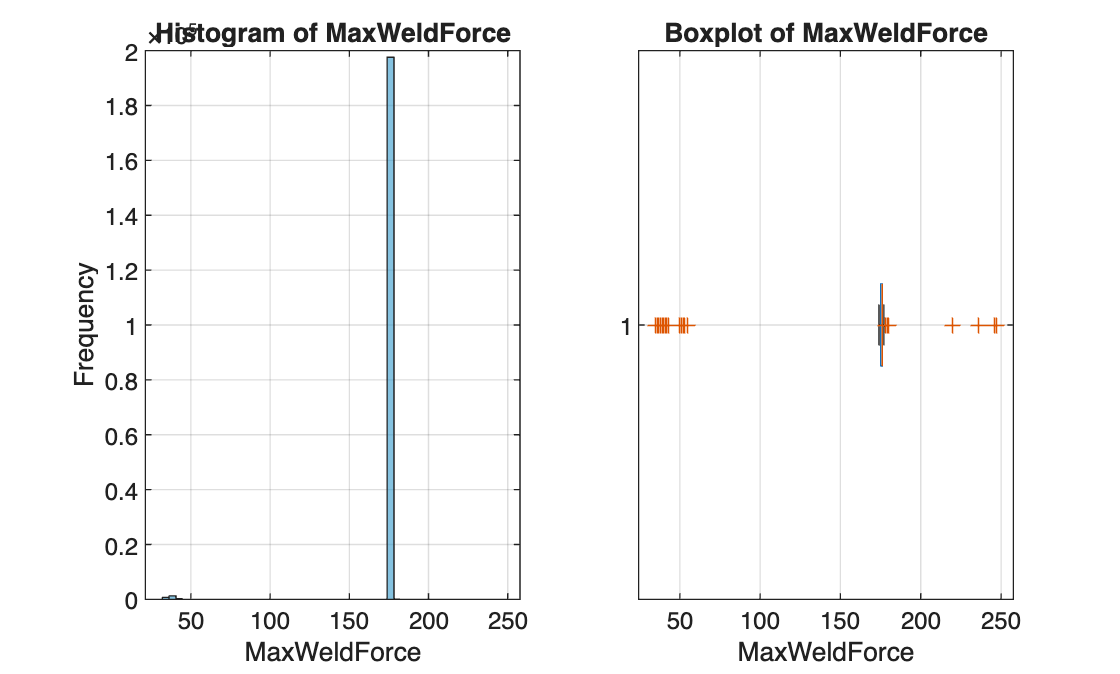

Parameter: MaxWeldForce


  Min: 35.000, Q1 (25%): 175.000, Median: 176.000, Q3 (75%): 176.000, Max: 247.000


  IQR: 1.000


  Mean: 174.107, Std: 14.733


  Skewness: -9.097, Kurtosis: 84.095


  Distribution Type: Left-skewed


  Dynamic Limits using IQR method: [173.500, 177.500]



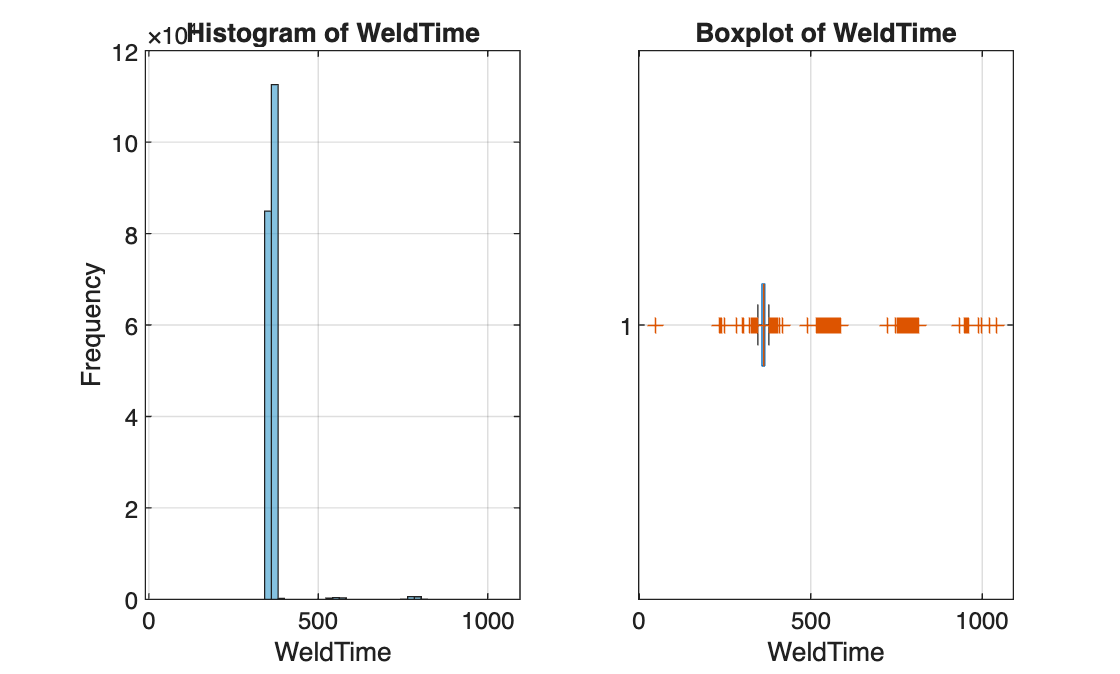

Parameter: WeldTime


  Min: 48.000, Q1 (25%): 358.000, Median: 363.000, Q3 (75%): 366.000, Max: 1041.000


  IQR: 8.000


  Mean: 366.013, Std: 37.141


  Skewness: 10.164, Kurtosis: 112.265


  Distribution Type: Right-skewed


  Dynamic Limits using IQR method: [346.000, 378.000]



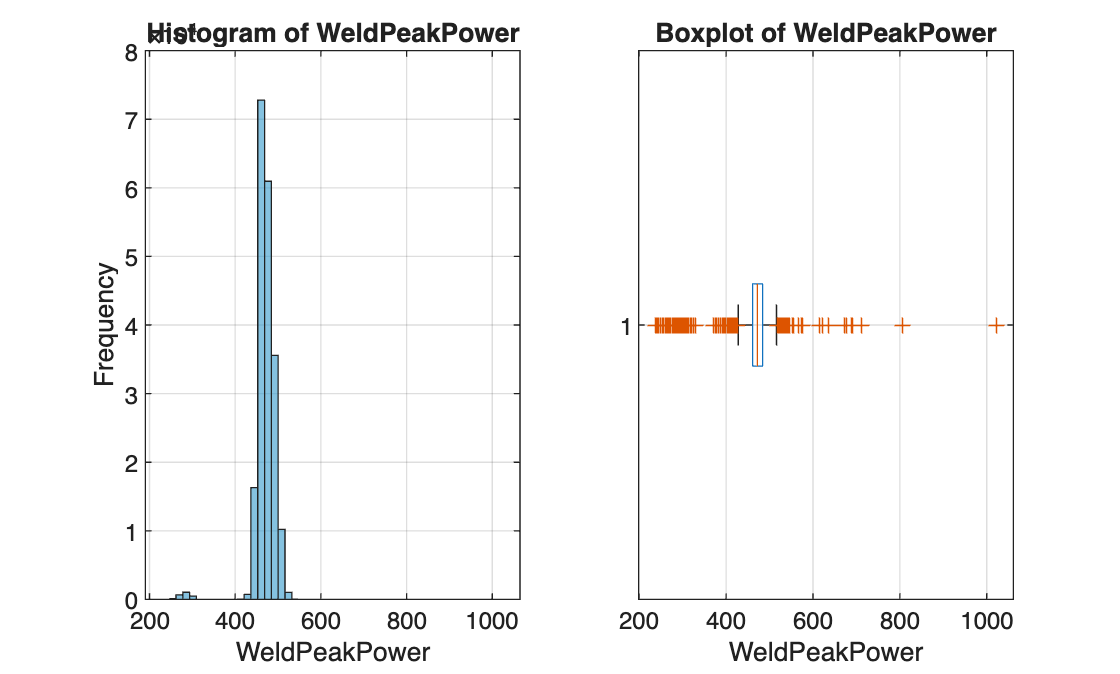

Parameter: WeldPeakPower


  Min: 238.000, Q1 (25%): 461.000, Median: 472.000, Q3 (75%): 484.000, Max: 1022.000


  IQR: 23.000


  Mean: 471.090, Std: 26.322


  Skewness: -4.013, Kurtosis: 32.672


  Distribution Type: Left-skewed


  Dynamic Limits using IQR method: [426.500, 518.500]



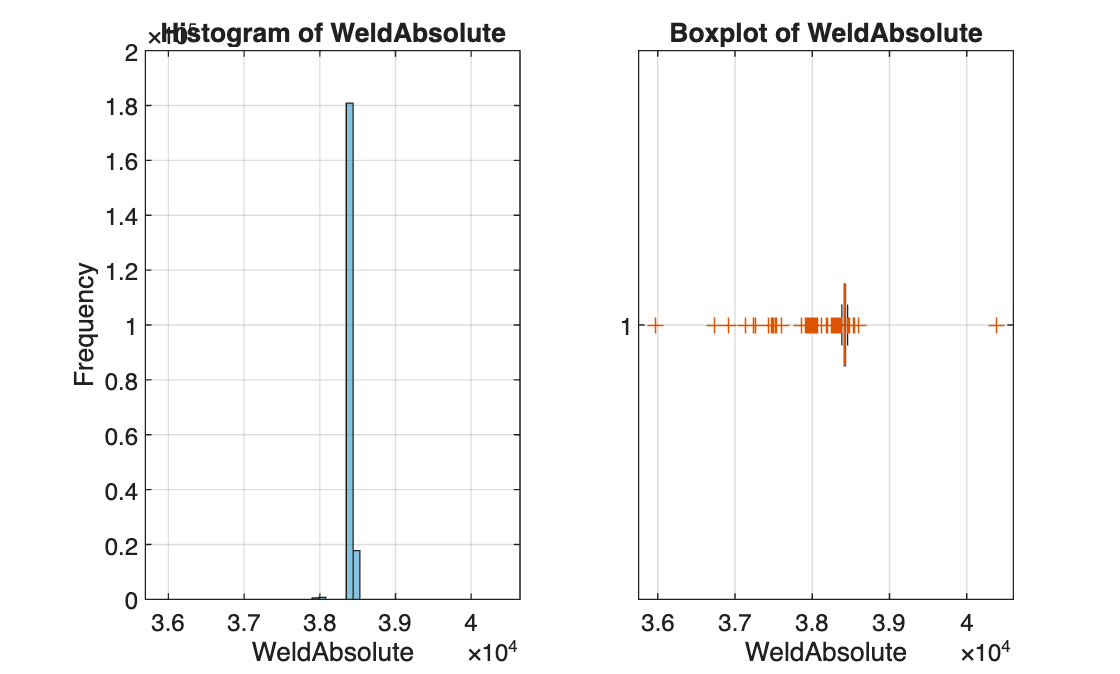

Parameter: WeldAbsolute


  Min: 35973.000, Q1 (25%): 38412.000, Median: 38421.000, Q3 (75%): 38431.000, Max: 40383.000


  IQR: 19.000


  Mean: 38418.054, Std: 39.280


  Skewness: -10.793, Kurtosis: 257.840


  Distribution Type: Left-skewed


  Dynamic Limits using IQR method: [38383.500, 38459.500]



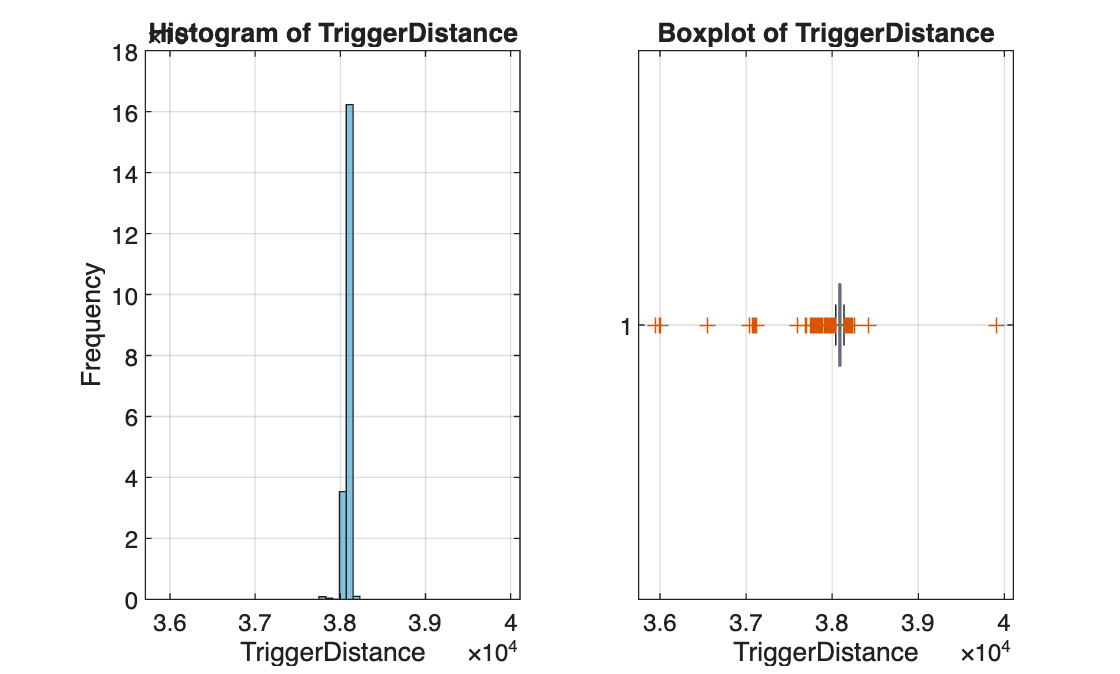

Parameter: TriggerDistance


  Min: 35950.000, Q1 (25%): 38077.000, Median: 38090.000, Q3 (75%): 38101.000, Max: 39906.000


  IQR: 24.000


  Mean: 38086.269, Std: 33.562


  Skewness: -14.261, Kurtosis: 755.572


  Distribution Type: Left-skewed


  Dynamic Limits using IQR method: [38041.000, 38137.000]



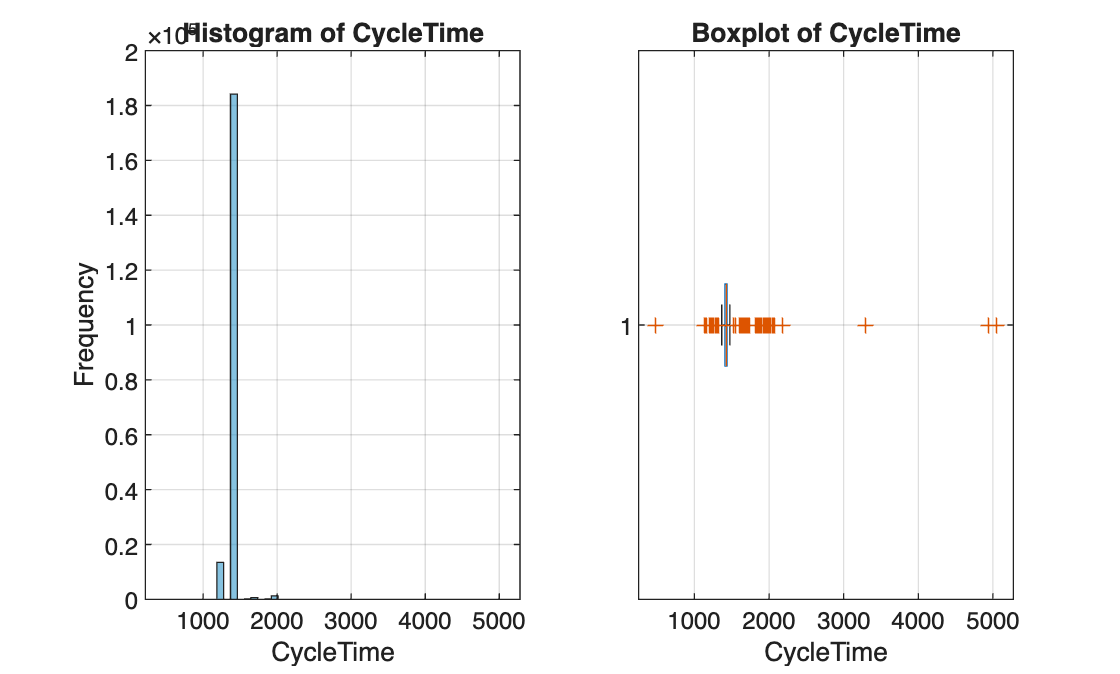

Parameter: CycleTime


  Min: 481.000, Q1 (25%): 1407.000, Median: 1429.000, Q3 (75%): 1437.000, Max: 5045.000


  IQR: 30.000


  Mean: 1415.936, Std: 72.470


  Skewness: 3.341, Kurtosis: 88.859


  Distribution Type: Right-skewed


  Dynamic Limits using IQR method: [1362.000, 1482.000]




for i = 1:numel(numVarNames)
    param = numVarNames{i};
    dataVec = selectedFeatures.(param);
    dataVec = dataVec(~isnan(dataVec));  % Remove NaNs

    figure('Name', ['Distribution of ', param], 'Color', 'w');
    
    % Plot histogram
    subplot(1,2,1);
    histogram(dataVec, 50, 'FaceColor', [0.2 0.6 0.8]);
    title(['Histogram of ', param], 'Interpreter','none');
    xlabel(param); ylabel('Frequency');
    grid on;

    % Plot boxplot
    subplot(1,2,2);
    boxplot(dataVec, 'Orientation', 'horizontal');
    title(['Boxplot of ', param], 'Interpreter','none');
    xlabel(param); grid on;

    % Compute distribution stats
    meanVal = mean(dataVec);
    stdVal = std(dataVec);
    minVal = min(dataVec);
    maxVal = max(dataVec);
    medianVal = median(dataVec);
    q1 = prctile(dataVec, 25);
    q3 = prctile(dataVec, 75);
    iqrVal = q3 - q1;
    skewVal = skewness(dataVec);
    kurtVal = kurtosis(dataVec);

    % Determine distribution type (simple heuristic)
    if abs(skewVal) < 0.5 && abs(kurtVal - 3) < 0.5
        distType = "Normal";
    elseif skewVal > 0.5
        distType = "Right-skewed";
    elseif skewVal < -0.5
        distType = "Left-skewed";
    elseif kurtVal > 3.5
        distType = "Peaked";
    elseif kurtVal < 2.5
        distType = "Flat";
    else
        distType = "Unknown";
    end

    % Choose limits method
    if distType == "Normal"
        lower = meanVal - 3 * stdVal;
        upper = meanVal + 3 * stdVal;
        method = 'Z-score';
    else
        lower = q1 - 1.5 * iqrVal;
        upper = q3 + 1.5 * iqrVal;
        method = 'IQR';
    end

    % Print everything
    fprintf('Parameter: %s\n', param);
    fprintf('  Min: %.3f, Q1 (25%%): %.3f, Median: %.3f, Q3 (75%%): %.3f, Max: %.3f\n', ...
        minVal, q1, medianVal, q3, maxVal);
    fprintf('  IQR: %.3f\n', iqrVal);
    fprintf('  Mean: %.3f, Std: %.3f\n', meanVal, stdVal);
    fprintf('  Skewness: %.3f, Kurtosis: %.3f\n', skewVal, kurtVal);
    fprintf('  Distribution Type: %s\n', distType);
    fprintf('  Dynamic Limits using %s method: [%.3f, %.3f]\n\n', method, lower, upper);
end

summaryTable = countThresholdAnomalies(selectedFeatures, params);

MaxWeldForce: 3990 anomalies detected
WeldTime: 3074 anomalies detected
WeldPeakPower: 3549 anomalies detected
WeldAbsolute: 2068 anomalies detected
TriggerDistance: 3115 anomalies detected
